clear all
clc;

## Radar Specifications

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8

## User Defined Range and Velocity of target

Define the target's initial position and velocity. Note : Velocity remains contant

R = 110; % initialize the distance of target
V = 20; % velocity (constant) can be any value in the range of -70 to + 70 m/s.

## FMCW Waveform Generation

%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.


%Operating carrier frequency of Radar 
fc= 77e9;             %carrier freq
maxRange = 200;       %m
rangeRes = 1;         %m
maxVel = 100;         %m/s
c = 3e8;              %m/s

B = c / (2*rangeRes);  % HZ
%  or V_max = wavelenght / (4*Tchirp) -> Tchirp = wavelength/(4*maxVel)
Tchirp = 5.5*2*maxRange / c; 
S = B / Tchirp;

%The number of chirps in one sequence. Its ideal to have 2^ value 
%for the ease of running the FFT for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
%r_t=zeros(1,length(t));
%td=zeros(1,length(t));

## Signal generation and Moving Target simulation

Running the radar scenario over the time. 

for i=1:length(t)         
   
    %For each time stamp update the Range of the Target for constant velocity. 
    R_update = R + V*t(i);
    tau = 2*R_update / c;
    
    %r_t(i) = R + V*t(i);
    %td(i) = 2*r_t(i) / 2;
    
    %For each time sample we need update the transmitted and
    %received signal. 
    Tx(i) = cos(2*pi*(fc*t(i) + S*t(i)^2/2));
    Rx(i)  = cos(2*pi*(fc*(t(i)-tau) + S*(t(i)-tau)^2/2));
    
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    %Here how to use dechirp to finish it.
    Mix(i) = Tx(i).*Rx(i);
end

## RANGE MEASUREMENT

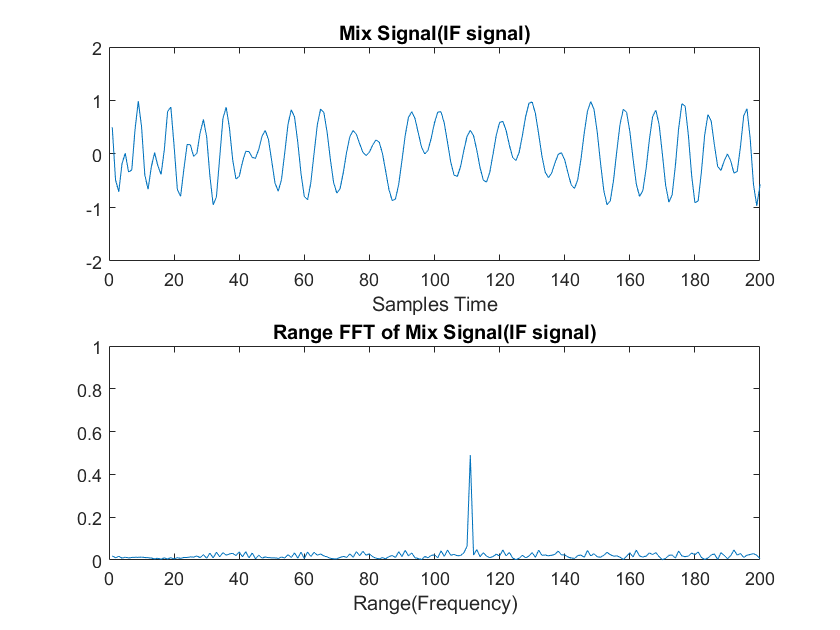

%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
Mix = reshape(Mix, Nr, Nd);

%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
range_FFT = fft(Mix,Nr);
range_FFT =range_FFT / (Nr/2);

% Take the absolute value of FFT output
range_FFT = abs(range_FFT);

% Output of FFT is double sided signal, but we are interested in only one side 
% of the spectrum.Hence we throw out half of the samples.
rFFT = range_FFT(1:Nr/2+1, :);

%plotting the Mix
figure ('Name','Range from First FFT')
subplot(2,1,1)
plot(Mix(:, 1));
axis ([0 200 -2.0 2.0]);
title('Mix Signal(IF signal)');
xlabel('Samples Time');
%ylabel('Ampltitude')

% plot FFT output 
subplot(2, 1, 2);
plot(rFFT(:, 1));
axis ([0 200 0 1.0]);
title('Range FFT of Mix Signal(IF signal)');
xlabel('Range(Frequency)')

%ylabel('Ampltitude')

## RANGE DOPPLER RESPONSE

The 2D FFT implementation is already provided here. This will run a 2DFFT on the mixed signal (beat signal) output and generate a range doppler map.You will implement CFAR on the generated RDM

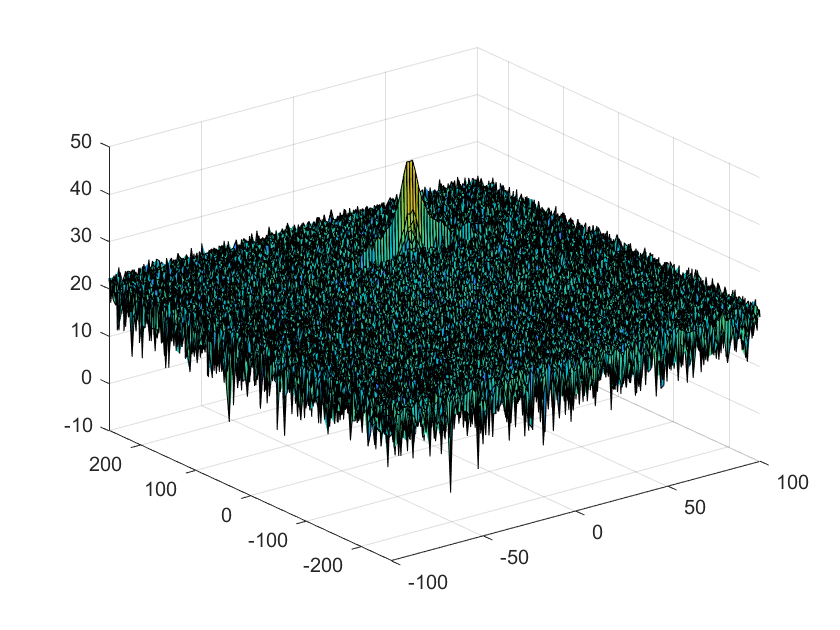

% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

## CFAR implementation

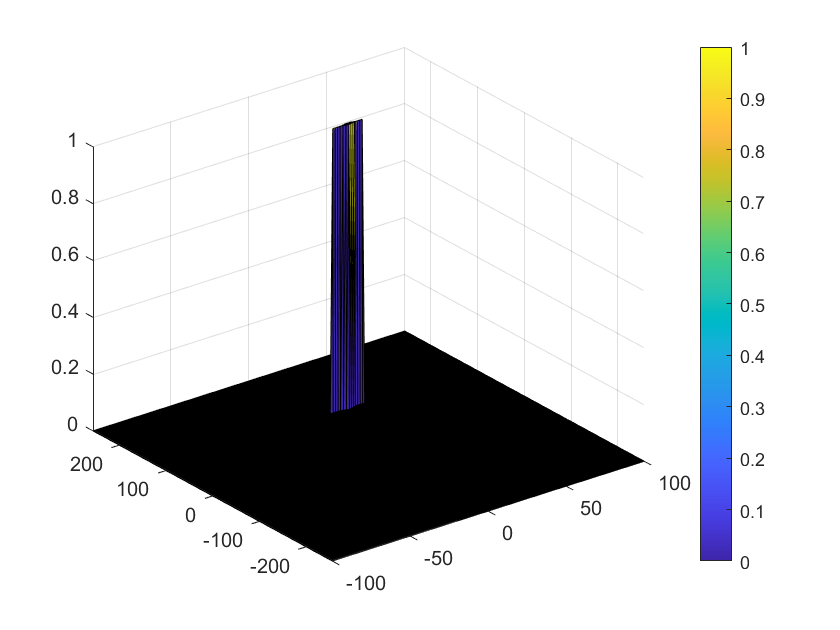

%Slide Window through the complete Range Doppler Map
%Select the number of Training Cells in both the dimensions.
Tr = 10;
Td = 8;

%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
Gr = 4;
Gd = 4;

% offset the threshold by SNR value in dB
offset = 6;

%Create a vector to store noise_level for each iteration on training cells
noise_level = zeros(1,1);
RDM_pow = db2pow(RDM);
Nr = Nr/2;

%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.
for i = Tr+Gr+1:Nr-(Tr+Gr)
    for j = Td+Gd+1:Nd-(Td+Gd)
        noise_level_matrix1 = RDM_pow(i-Tr-Gr:i+Tr+Gr,j-Td-Gd:j+Td+Gd);
        noise_level_matrix2 = RDM_pow(i-Gr:i+Gr,j-Gd:j+Gd);
        noise_level = sum(noise_level_matrix1(:)) - sum(noise_level_matrix2(:));
        threshold = offset + pow2db(noise_level/(2*(Tr+Gr+1)*2*(Td+Gd+1) - ...
            2*(Gr+1)*2*(Gd+1)));
        CUT = RDM(i,j);
        if(CUT < threshold)
            RDM(i,j) = 0;
        else
            RDM(i, j) = 1;
        end        
    end
end
% The process above will generate a thresholded block, which is smaller 
%than the Range Doppler Map as the CUT cannot be located at the edges of
%matrix. Hence,few cells will not be thresholded. To keep the map size same
% set those values to 0. 
RDM(1:Tr+Gr,:)=0;
RDM(Nr-(Tr+Gr):Nr,:)=0;
RDM(:,1:Td+Gd)=0;
RDM(:,Nd-(Td+Gd):Nd)=0;

%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.
figure,surf(doppler_axis,range_axis,RDM);
colorbar;